%calculating the mean first passage time analytically/numerically 
%to investigate effect of incumbent and invader toehold lengths on DNA/RNA
%toehold exchange kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

%g = 2 %define invader toehold length
%g2 = 4 %define incumbent toehold length


R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -0.1*R*temp

dGrd = -0.0592

dGbm = 7.4*R*temp

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 15)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 15)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through incumbent toehold lengths
for g2 = 2:7
    bg2 = b + g2 %define branch migration domain + incumbent toehold length
    %loop through invader toehold lengths
    for g = 1:15
        g
        
        %define forward and reverse transition rates
        k_AA = 0;
        k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
        k_B1A = k_bp * exp(dGbp/(R*temp))
        k_BC1ij = k_bp;
        k_BC1ji = k_bp * exp(dGbp/(R*temp));
        k_C1f = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
        k_Cf = k_bp * exp(-(dGbm - dGrd)/(R*temp))
        k_Cr = k_bp * exp(-dGbm/(R*temp));
        k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
        k_DEij = k_bp * exp((dGbp + dGrd)/(R*temp));
        k_DEji = k_bp;
        k_EF = k_bp *exp((dGbp + dGrd)/(R*temp))
        k_FE = 0
        k_FF = 1    
    
        %create arrays of forward and reverse transition rates
        if g == 1
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_B1A, k_AA]
        
            %define spontaneous incumbent dissociation rates
            Koff = [repmat(0, [1, g2+1])];
            for n = g2+1:bg2-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
            end
            Koff = horzcat(Koff, [0, 0])
            
        else
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
            %define spontaneous incumbent dissociation rates
            Koff = [repmat(0, [1, g2+1])]; 
            for n = g2+1:bg2-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
            end
            Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        end
    
        Pn_jN_1 = zeros(1,numel(Kf))
        jn_jN_1 = zeros(1,numel(Kf))
        Pn_jN_1 (1) = 0;
        jn_jN_1 (1) = 1;
        %calculate flux between each state
        for Pn = 2:numel(Kf)
            Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
            jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
        end
        
        first_pass_time (g2-1, g) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %calculate first passage time 
        k_eff (g2-1, g) = 1/(first_pass_time (g2-1, g)*(5*10^-8)); %calculate effective rate constant
        prob_unbound(g2-1, g) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate probability of being in unbound state
    end
end

bg2 = 22

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+06 *

    0.0000    3.9314    3.9314    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0008    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+06 *

    1.5151         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+06 *

    1.5151    0.1219         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+06 *

    1.5151    0.1219    0.0098         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+06 *

    1.5151    0.1219    0.0098    0.0008         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+06 *

    1.5151    0.1219    0.0098    0.0008    0.0001         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+06 *

    1.5151    0.1219    0.0098    0.0008    0.0001    0.0000         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+06 *

    1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    2.0837    0.1517    0.0110    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840


bg2 = 23

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    3.9314    3.9314    3.9314    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0008    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.5170    0.1104    0.0080    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830


bg2 = 24

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    3.9314    3.9314    3.9314    3.9314    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0008    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0  110.4425    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816


bg2 = 25

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    3.9314    3.9314    3.9314    3.9314    3.9314    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0008    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001    0.0000         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    8.0405    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.5151    0.1219    0.0098    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.6087    0.1294    0.0104    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7245    0.1388    0.0112    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    3.1711    0.2552    0.0205    0.0017    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647


bg2 = 26

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    3.9314    3.9314    3.9314    3.9314    3.9314    3.9314    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0008    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001    0.0000         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.5854    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.1515    0.0122    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1609    0.0129    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1725    0.0139    0.0011    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3171    0.0255    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.3030    0.1853    0.0149    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798


bg2 = 27

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    3.9314    3.9314    3.9314    3.9314    3.9314    3.9314    3.9314    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0008    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001    0.0000         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9806         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9806    0.8120         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9806    0.8120    0.3745         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9806    0.8120    0.3745    0.2305         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9806    0.8120    0.3745    0.2305    0.2159         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9806    0.8120    0.3745    0.2305    0.2159    0.2147         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9806    0.8120    0.3745    0.2305    0.2159    0.2147    0.2146         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9806    0.8120    0.3745    0.2305    0.2159    0.2147    0.2146    0.2146         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9806    0.8120    0.3745    0.2305    0.2159    0.2147    0.2146    0.2146    0.2146         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 901.8918

k_EF = 3.9314e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.3931    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0         0    0.0426    0.0031    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0152    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0172    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0317    0.0026    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2303    0.0185    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.9581    0.2380    0.0192    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9917    0.9851    0.9841    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840    0.9840
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9914    0.9843    0.9831    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830    0.9830
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9911    0.9831    0.9818    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816    0.9816
    1.0000    1.0000    1.0000    0.9999    0.9986    0.9878    0.9694    0.9651    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647    0.9647
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9819    0.8840    0.7946    0.7810    0.7799    0.7798    0.7798    0.7798    0.7798    0.7798
    1.0000    1.0000    1.0000    0.9999    0.9984    0.9806    0.8120    0.3745    0.2305    0.2159    0.2147    0.2146    0.2146    0.2146    0.2146


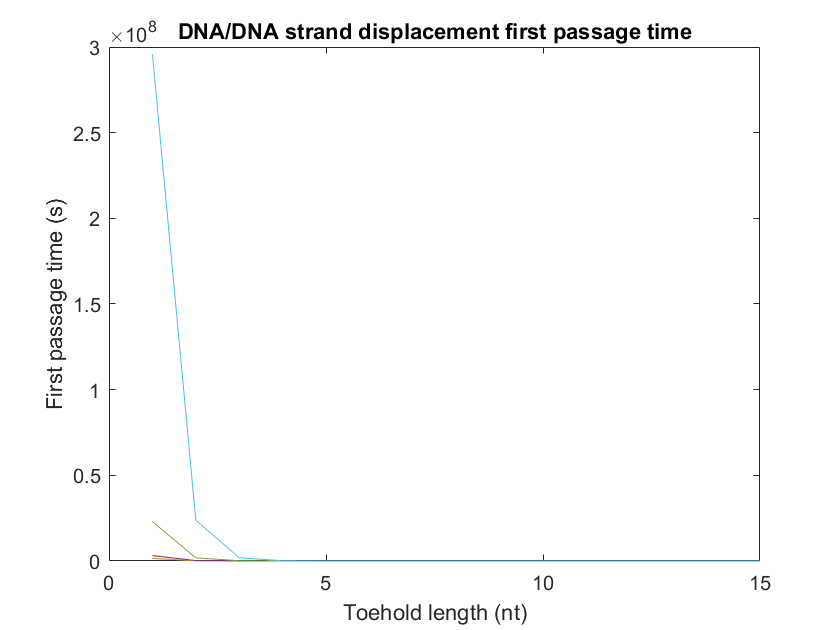

plot(1:15, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

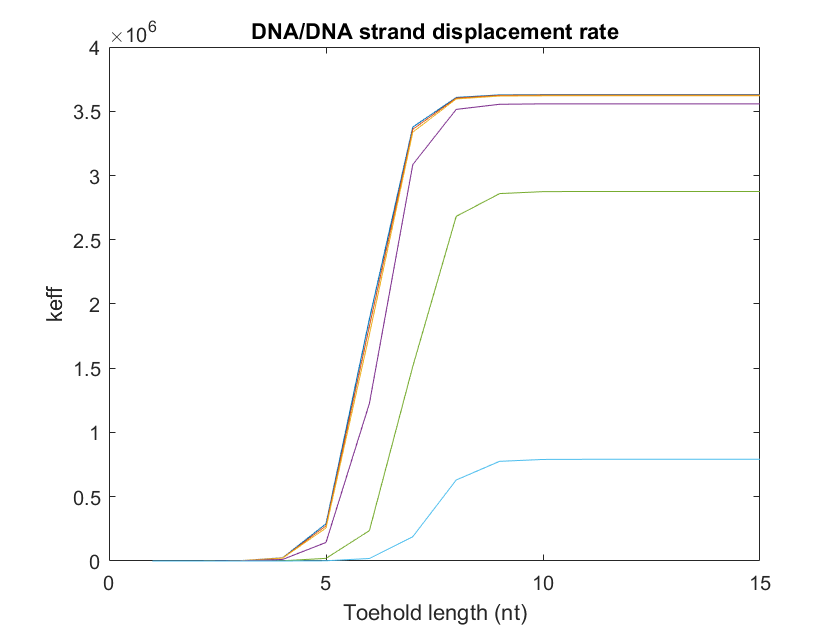


plot(1:15, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

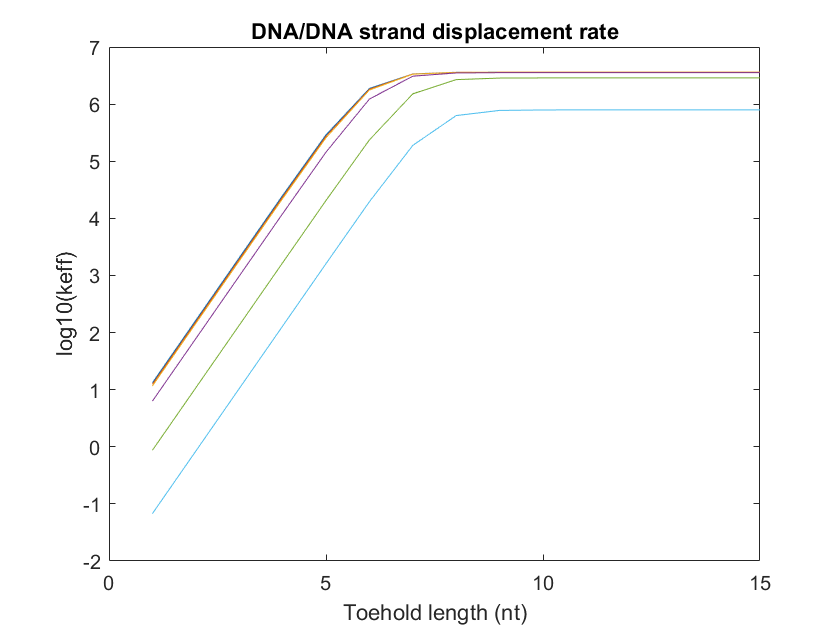


plot(1:15, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  